% Board Size (Note that the board size will be one less than the numbers
% you choose)
rows = 15;
columns = 15;

limitC = columns - 1;
limitR = rows - 1;

% Treasure location
treasureX = randi(limitC);
treasureY = randi(limitR); 

% Creates the blank map
map = zeros(rows, columns);
map(map == 0) = NaN;

% Creates the colored in map
xCoords = 1:columns;
yCoords = 1:rows;
finalMap = abs(treasureY - xCoords) + abs(treasureX - yCoords)';

% Set the treasure to a high value so it appears correctly
finalMap(treasureY,treasureX) = rows*2;

% The colormap for the board with different colors to simulate an island
cmap = [0.6706 0.4588 0.0392; 0.4667 0.6745 0.1882; 0 1 0;1 0.9059 0.5216;0.0588 1 1; 0 0 1; 0 0.4471 0.7412;0.0314 0 0.4706; 1 1 0];

% Number of guesses the player has made
numGuesses = 0;

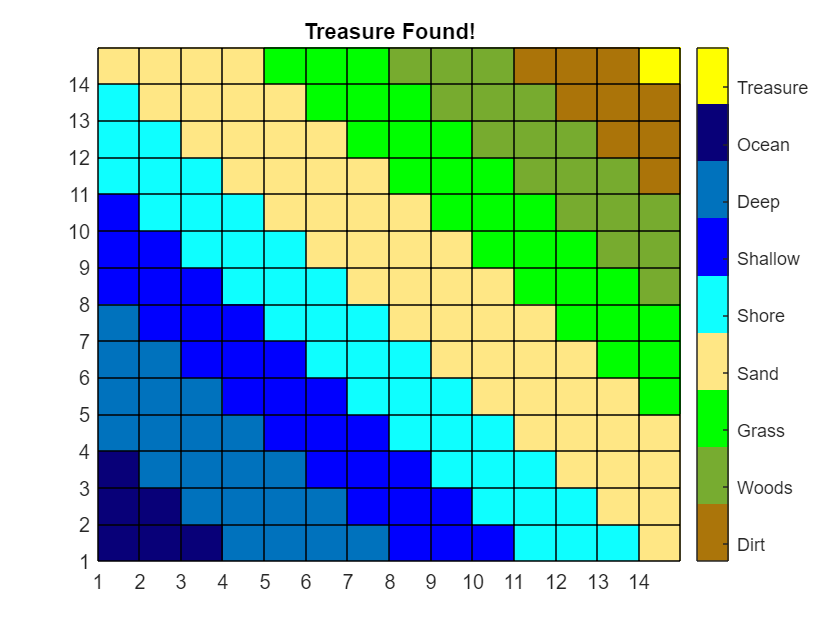

%Board Setup
p = pcolor(map);
hold on
xticks(1:1:limitC);
yticks(1:1:limitR);

colormap(cmap);
clim([0 rows*2]);

c = colorbar;
c.Ticks = 1:rows*2/9:rows*2;
c.TickLabels = {'Dirt','Woods','Grass','Sand','Shore','Shallow','Deep','Ocean', 'Treasure'};

title("Find the Treasure!")

%Play Game
 

if(numGuesses ~= 0)
    guessX = 14;
    guessY = 14;

    %Run function to check guesses
    playGame(treasureX,treasureY,map,finalMap,guessX,guessY,numGuesses)
    numGuesses = numGuesses + 1;
else
    %Increments the Guess Numbers to start the game
    numGuesses = numGuesses + 1;
end

function playGame(treasureX,treasureY,map,finalMap,guessX,guessY,numGuesses)
    % If the treasure has been found
    if(guessX == treasureX)&&(guessY == treasureY)
        % Display the finalMap
        pcolor(finalMap);

        % Change the title to "Treasure Found!"
        title("Treasure Found!");

    % If the treasure has not been found
    else
        % Set the guessed location in map equal to the guessed location in
        % finalMap
        map(guessY,guessX) = finalMap(guessY,guessX);

        % Display the updated map
        pcolor(map);
        
        % Tell the player how far they are from the
        % treasure, and how many guesses they've taken so far
        help = "You are " + string(finalMap(guessY,guessX)) + " away from the treasure.";
        guess = "Guess: " + numGuesses;
        disp(help);
        disp(guess);
        disp("Guess again!");
    end
end